# 最小功率算法

前面三种算法，需要知道有用信号的来向信息或已知参考信号。因此如果将MSINR和MVDR两种准则用于卫星导航抗干扰中，需要知道卫星信号的来向信息，实现起来相对复杂。如果利用MMSE准则，则需要获得参考信号，即需要知道卫星信号。

以GPS为例，当卫星信号和Q个干扰信号入射到M元均匀线阵上时，t时刻接收到的信号模型为

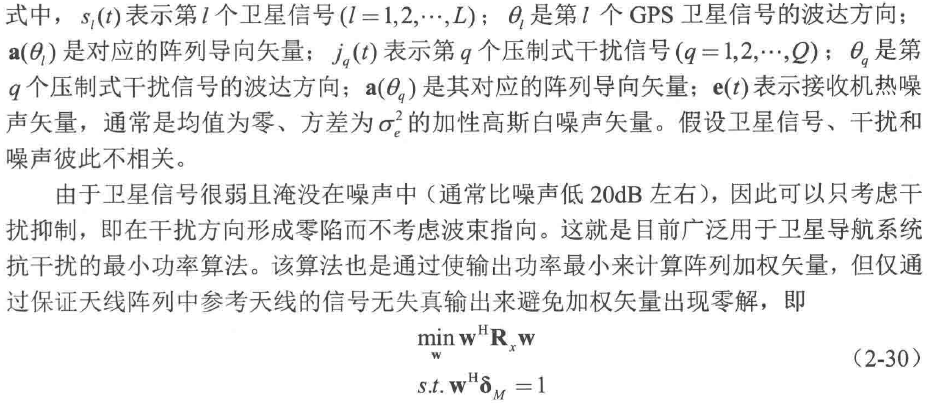

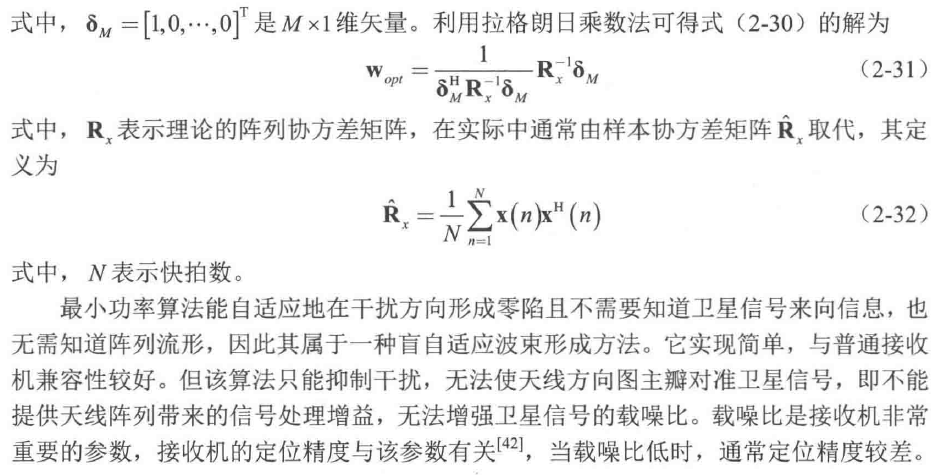

%--------------------------------------------------------------------------
%   初始化
%--------------------------------------------------------------------------
clear;clc;

%--------------------------------------------------------------------------
%   参数设置
%--------------------------------------------------------------------------
N = 16;                                                                     %阵元个数
theta = [-10 0 10 30];                                                      %信号 干扰 干扰
M = numel(theta);                                                           %信源个数
snr = 10;                                                                   %信噪比
K = 1024;                                                                   %采样点数

%--------------------------------------------------------------------------
%   生成3个来向的导向矢量
%--------------------------------------------------------------------------
c = 3e8;                                                                    %光速
lambda = 1;                                                                 %波长
dd = lambda/2;                                                              %阵元间距d = lambda/2
d = 0:dd:(N-1)*dd;                                                          %构建阵列坐标
A = exp(1j.*2*pi*d.'*sind(theta));                                          %构建阵列流形

%--------------------------------------------------------------------------
%   接收信号为随机值
%   并按照阵列流形构造回波相位                                  
%--------------------------------------------------------------------------
S = randn(M,K) + 1j.*randn(M,K);                                            %构建接收信号
S(1,:) = S(1,:).*0.1;                                                       %信号功率小，干扰功率大,如果信号功率大了 也会默认为干扰位置
X = A*S;                                                                    %对信号来向进行仿真
X1 = awgn(X,snr,'measured');

%--------------------------------------------------------------------------
%   构造接收信号的协方差矩阵
%--------------------------------------------------------------------------
Rx = X1*X1';

%--------------------------------------------------------------------------
%   构造delta_m 约束最小功率
%--------------------------------------------------------------------------
delta_m = zeros(N,1);delta_m(1) = 1;

%--------------------------------------------------------------------------
%   最优权矢量为
%--------------------------------------------------------------------------
w_opt = (Rx^-1*delta_m)/(delta_m'*Rx^-1*delta_m);

%--------------------------------------------------------------------------
%   绘制天线方向图
%--------------------------------------------------------------------------
idx = 1;
for theta_d = -90:0.1:90
    A1 = exp(1j.*2*pi*d.'*sind(theta_d));
    output(idx) = w_opt'*A1;
    idx = idx + 1;
end

%--------------------------------------------------------------------------
%   计算 信号 干扰角度
%--------------------------------------------------------------------------
for idx = 1:length(theta)
    index(idx) = find([-90:0.1:90]==theta(idx));
end

figure(1)
plot(-90:0.1:90,db(abs(output)));grid on;hold on
plot(theta,db(abs(output(index))),'o');
hold off